clc
clear all
close all

## Simulacion

Condições iniciais

clear all;  clc; close all;
nit = 400; umin = 0; umax = 4.9; ts = 0.1;
u(1:10) = 0; erro(1:10) = 0; y(1:10) = 0;
% Referência
r(1:100) = 1; r(101:200) = 4; r(201:300) = 3; r(301:nit) = 3;

## Planta

T=0.005;                          %Tempo da Amostragem
num=4.105;                          %Numerador Continuo
den=[0.2475 1 0];                %Denominador Continuo
gp=tf(num,den);                 %Função de transferencia
ftz=c2d(gp,T);                  %Planta Discreta
[B,A]=tfdata(ftz,'v');          %Divide Numerador em B e denominador em A
nb=length(B);                   %Ordem do numerador
na=length(A)-1;                 %Ordem do Denominador
nr=nb-1;                        %Ordem do polinomio R
ns=na;                        %Ordem do Polinomio S
gpz=filt(B,A,T,'name','Planta');      %Funcao de transferenca discreta

## PMF

%Alocaçao de polos por condições de disenho.
Ts=0.5;                     %Tempo de estabelecimento desejado
ep=0.6901;                     %Epsilon 
wn=4/(ep*Ts);               %
%Polos conjugados
za=exp(-ep*wn*T);
th=57.3*wn*T*sqrt(1-ep^2);
polos=za*[cosd(th)+i*sind(th),cosd(th)-i*sind(th)];
% Polinomio desejado, com polo insignificante igual a zero
Am=poly([polos 0 0]);
%Delata A. Multiplica por integrador
DA=conv(A,[1 -1]);
%Resolução de Equações metodo matricial
M=[1 B(2) 0 0; DA(2) B(3) B(2) 0; DA(3) 0 B(3) B(2);DA(4) 0 0 B(3)];
q=[Am(2)-DA(2); Am(3)-DA(3);Am(4)-DA(4);Am(5)];
X=inv(M)*q;
R=[1 X(1)];             %Polinomio R
S=X(2:end)';            %Polinomio S
%Polinomio T
Tz=sum(S);
%Ingresa la perturbacion en el instante 300
d0(1:300)=0;
d0(301:nit)=0.05;
for k = 5:nit
%Salida de la Planta
y(k)=B(2)*u(k-1)+B(3)*u(k-2)-A(2)*y(k-1)-A(3)*y(k-2)+d0(k);
%Ley de Control
u(k)=Tz*r(k)-S(1)*y(k)-S(2)*y(k-1)-S(3)*y(k-2)-(R(2)-1)*u(k-1)+R(2)*u(k-2);
%     Saturação
if u(k) >= umax 
u(k) = umax;
elseif u(k) <= umin
u(k) = umin;
end
end
t = 0:ts:(nit-1)*ts;
figure
subplot(2,1,1),plot(t,r,'--k',t,y,'-r','Linewidth',2.5)
xlabel('Tempo (s)');
ylabel('Velocidade');
legend('y_r','y','Location','SouthEast')
grid on;
hold

Current plot held


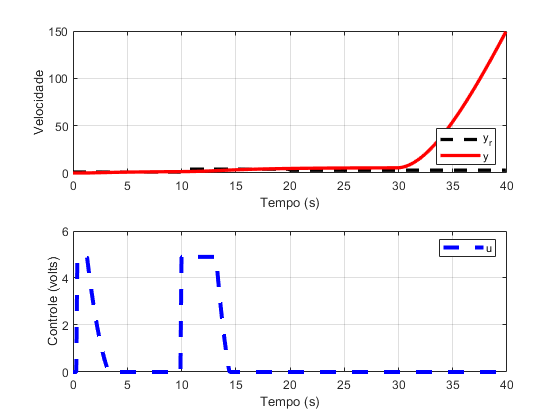

subplot(2,1,2),plot(t,u,'--b','Linewidth',3)
xlabel('Tempo (s)');
ylabel('Controle (volts)');
legend('u')
grid on;